# **ELEC 5508  Wireless Engineering Lab 7 (2025)**

# **Objectives **

The teaching team of the University of Sydney for **ELEC5508 Wireless Engineering**, in collaboration with **MathWorks subject matter experts**, has developed materials specifically designed to study **AI applications in wireless engineering.** The main objectives of this lab are to investigate, apply and implement **AI receiver to enhance Wireless Communications**. These activities within this lab will extend from the previous practical exercises on OFDM and MIMO by incorporating Machine Learning/Neural Networks into the signal processing chains of Wireless Communication Systems. Students will

- learn and develop **an AI application** 

- model and simulate **Wireless Communications **

- apply and implement **Machine Learning/Neural Networks** within Wireless Communication systems.

# **Introduction  **

Wireless Communications and AI are two different disciplines, from telecommunications and computer science, respectively. Combining both disciplines enables us to develop a revolutionary technology that is useful to solve real-world problems nowadays. In this lab series, we will learn and practice to use AI in wireless engineering technologies (e.g. OFDM, MIMO and SDR).

AI has been extensively researched to support the development of the next generation of wireless devices. In this lab, we will learn how to apply the AI technique (based on a widely used open-source framework) to improve wireless communication systems. Note that AI is not a silver bullet that can solve all the problems in wireless engineering. It also has limitations, and how successful it would become depends on how the engineers (i.e. us) develop and deploy it.  

This lab serves as an introduction to the new area of AI-enhanced signal processing in Wireless Communications. 

- The first part of the lab is to learn and use [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html) to build some AI applications throughout the entire development workflow.

- The second part is to explore this GPU-accelerated frame for developing some link-level modeling and simulation.  

- The third part is to implement Neural Receiver for OFDM Systems. Neural network symbol detectors provide novel and alternative detections to the Equaliser and Demodulation-based receivers that we cover in the earlier labs.  

**Make sure you have the necessary toolboxes installed**

- [**Deep Learning Toolbox**](https://www.mathworks.com/products/deep-learning.html)  

- [**Communications Toolbox**](https://au.mathworks.com/products/communications.html)  

- [**5G Toolbox**](https://au.mathworks.com/products/5g.html) 

- [**Phased Array System Toolbox**](https://au.mathworks.com/products/phased-array.html)  

Start with a clean configuration.  Clear workspace and close figures 

clear, close all 

# **Experiment 1: MATLAB-Based AI application **

## **1) Configuration of Neural Network **

The first step is to configure a **neural network**. In neural network, the quality of the data may be as important as the neural network itself. In this example, we will take a simple input (i.e. x) to the output (i.e y) govened by the underlying funcion given as y = 2x^2 + 6x - 10.

The Neural Network to model a second-order equation consists of a lambda layer and one dense layer (1 neuron).

**Define the Custom Layer (x → [x, x²])   **

See StackXandX2Layer.m  

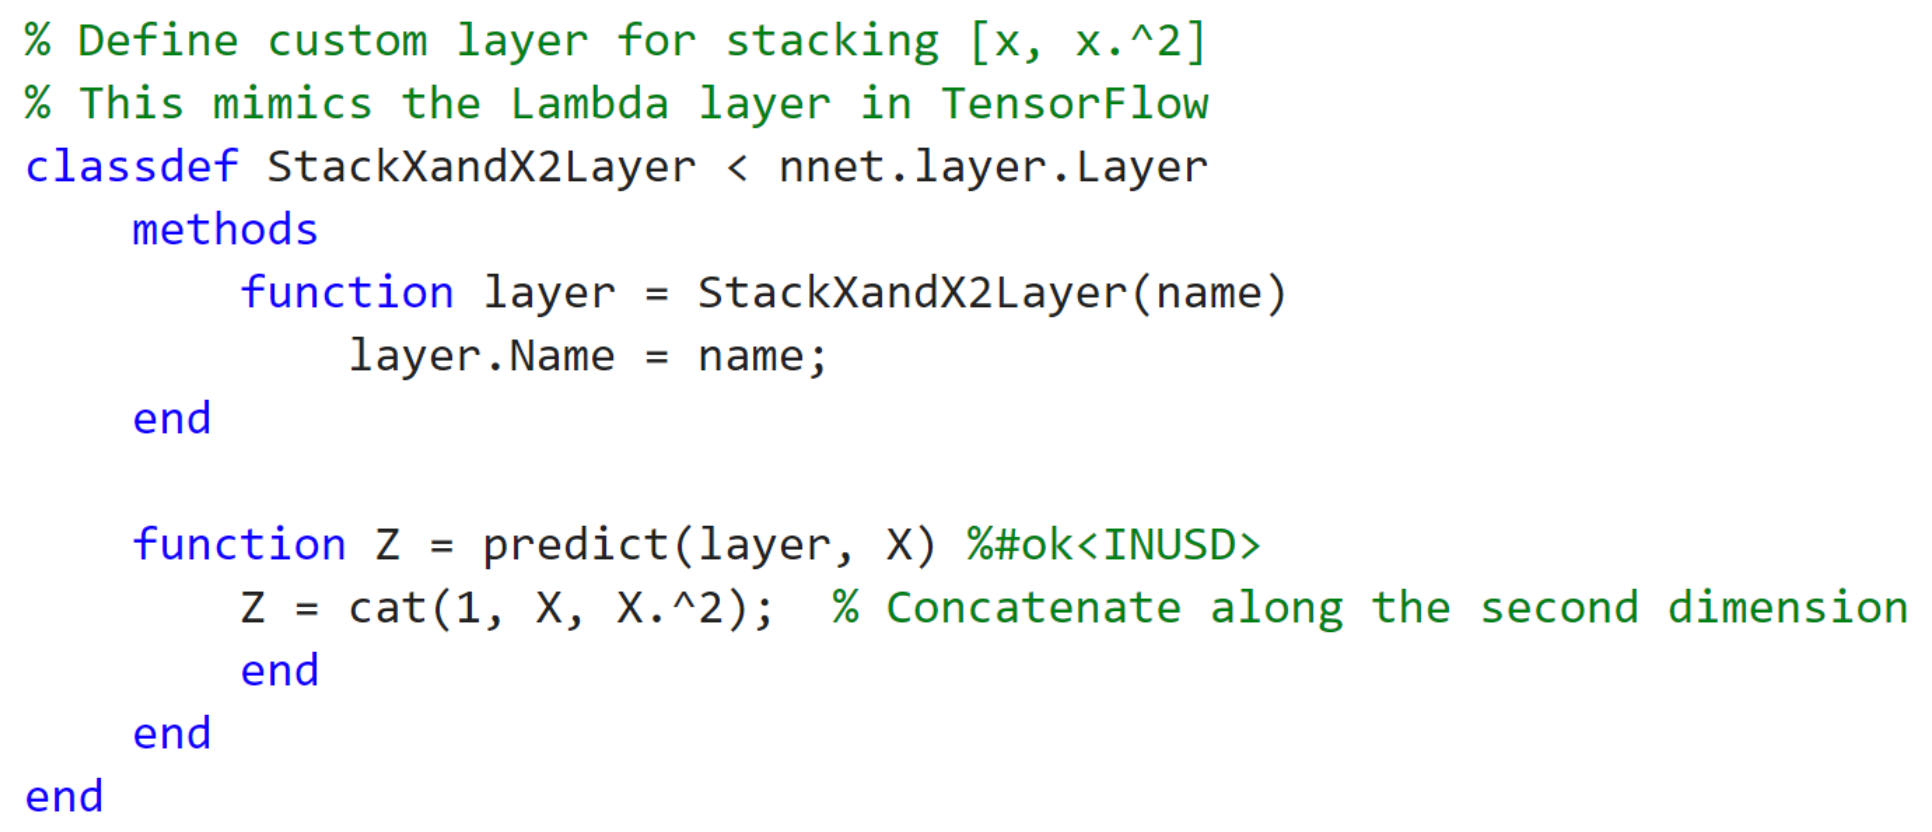  

**Build the network **

layers = [
    featureInputLayer(1, 'Name', 'input')
    StackXandX2Layer('stack_x_x2')
    fullyConnectedLayer(1, 'Name', 'fc', 'WeightsInitializer', 'narrow-normal')
];

## **2) Training the Neural Network **

The underlying function is defined as 2x^2+6x−10. x and y are the data (somehow we could measure 51 sets of data) feeding to train the Model. Note that in the real world scenarios, we never know the underlying function at the start. In this example, we define the underlying function so we can compare it with the model prediction.

**Generate Dataset **

x = linspace(-4, 4, 101)';
f = @(x) 2*x.^2 + 6*x - 10;
y = f(x) + randn(size(x));  % Add Gaussian noise

**Visualize the Data**

We can visulise our 51 sample data with the following codes.

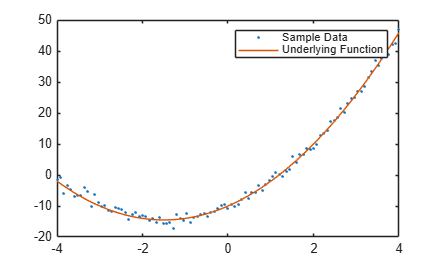

cla; % Clears the current axes
plot(x, y, '.', 'DisplayName', 'Sample Data');
hold on;
plot(x, f(x), 'DisplayName', 'Underlying Function');
legend; 

Then we need to specify a loss function (mean squared error) and an optimizer (Stochastic gradient descent). The starting learning rate is 0.005.  

Okay, assume that we have some measured data. Training the neural network is to learn the relationship between the input Xs and output Ys, specifically using the model.fit call. The process starts with an estimation, and measure the loss function, and use the opimizer to try another estimation until some satisficatory result could be reached. It will continue the looping process according to **epochs** (i.e. 25).

**Set Training Options **

Note that "mse" is used later in trainnet  

LearnRate = 0.007;  
opts = trainingOptions("sgdm", ...
    "InitialLearnRate", LearnRate, ... 
    "MaxEpochs", 150, ...
    "Plots", "training-progress", ...
    "Verbose", true, ...
    "VerboseFrequency", 1);

**Train the model **

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:00        0.007          288.55
            2        2       00:00:00        0.007          211.79
            3        3       00:00:00        0.007          181.92
            4        4       00:00:00        0.007          156.44
            5        5       00:00:00        0.007          83.634
            6        6       00:00:00        0.007          48.076
            7        7       00:00:00        0.007          66.266
            8        8       00:00:00        0.007          65.311
            9        9       00:00:00        0.007          60.045
           10       10       00:00:00        0.007          88.384
           11       11       00:00:00        0.007          104.46
           12       12       00:00:00        0.007          87.529
           13       13       00:00:00        0.007          78

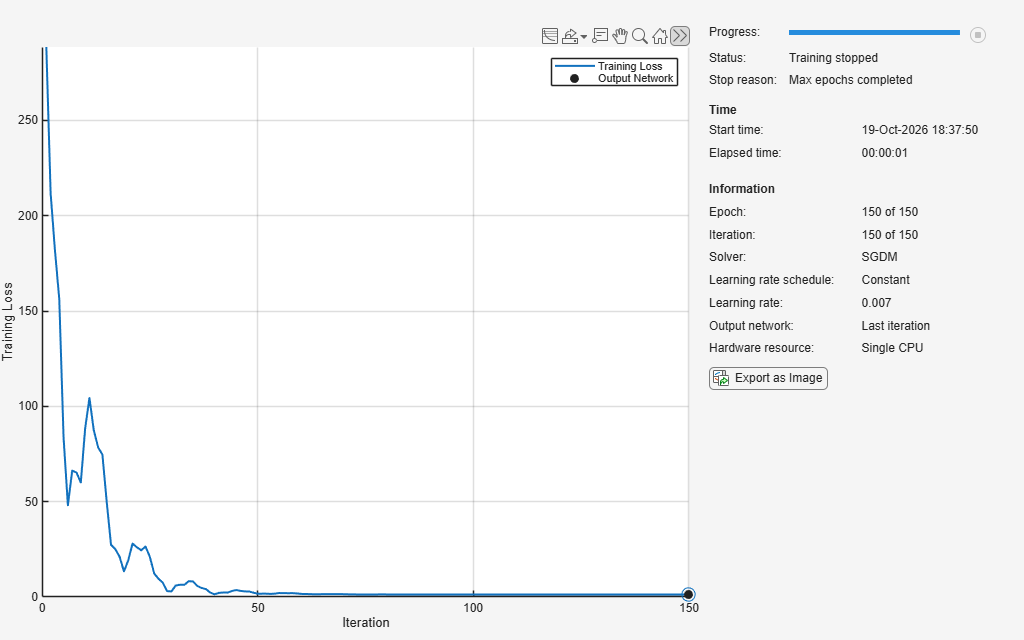

[net, info] = trainnet(x, y, layers, "mse", opts);

**Save the model **

save("Model_Exp1.mat", "net"); 

## 3) Test and Evaluate the Model

Let's see how good (or bad) our model is.

For example, say we have another input x=4 (choose one value that does appear in the data set), what is the prediction from the model? Compare it with the direct calcuation from the underlying equation. How good (or bad) is your prediction?

**Predict a Value **

xTest = 4.0;
yPred = predict(net, xTest);
disp("Prediction at x = 4.0: " + yPred); 

Prediction at x = 4.0: 46.0023


**Plot Training Loss Over Epochs **

We can also see the progress of Neuron Network training progress by plotting the Loss Function with Epoch. 

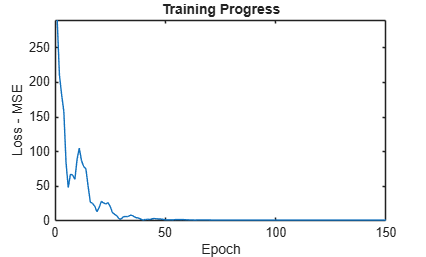

figure;
plot(info.TrainingHistory.Loss);
xlabel('Epoch');
ylabel('Loss - MSE');
title('Training Progress');
ylim([0, max(info.TrainingHistory.Loss)]);

Next, use the new dataset to test the model. **Remember that we should always use '*****unseen*****' data to verify the model!**

Let's plot the model predications in comparison to the underlying function. This gives us some indications on the performance of the model.  

**Plot Model vs Underlying Function** 

Define x range

xPlot = linspace(4, 12, 20)';

Underlying function

f = @(x) 2*x.^2 + 6*x - 10;

Model predictions

yModel = predict(net, xPlot); 

Plot comparison

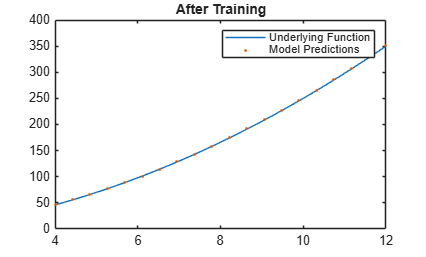

figure;
plot(xPlot, f(xPlot), 'DisplayName', 'Underlying Function');
hold on;
plot(xPlot, yModel, '.', 'DisplayName', 'Model Predictions');
title('After Training');
legend;

Last, we can check the weights of the model by executing the following codes. How do they compare to the coefficients of the underlying funcion 2x^2+6x−10? 

**Inspect Weights and Bias  **

Access weights and bias from the fully connected layer

fcLayer = net.Learnables(net.Learnables.Layer == "fc", :);

weights = fcLayer.Value{1};  % 1×2 vector: coefficients for x and x²
bias = fcLayer.Value{2};     % scalar bias

disp("Weights (coefficients for x and x²):");

Weights (coefficients for x and x²):


disp(weights);

  1×2 single dlarray

    5.9204    2.0183




disp("Bias:");

Bias:


disp(bias);

  1×1 single dlarray

   -9.9727



## 4) Exercise

**1: Briefly describe the workflow of developing a Neural Network Application.**

**2: Try to use different values for epochs. Describe the Training Loss Curve. How could the choice of epochs affect the performance of the model? Note that to retrain the model, we need to start again from the Configuration steps.**

**3: Try to use different values for the learning rate. How could the choice of the learning rate affect the performance of the model?**

**4: Find the optimal combination of epochs and learning rate that gives you both efficiency and performance. Justify your choices. Note that the optimal combination is always data dependent, and the only way to find it out is experimentation.**

**5: Why is there a difference between the curves of model predictions and underlying function ? **

# **Experiment 2: 5G Communication Systems **

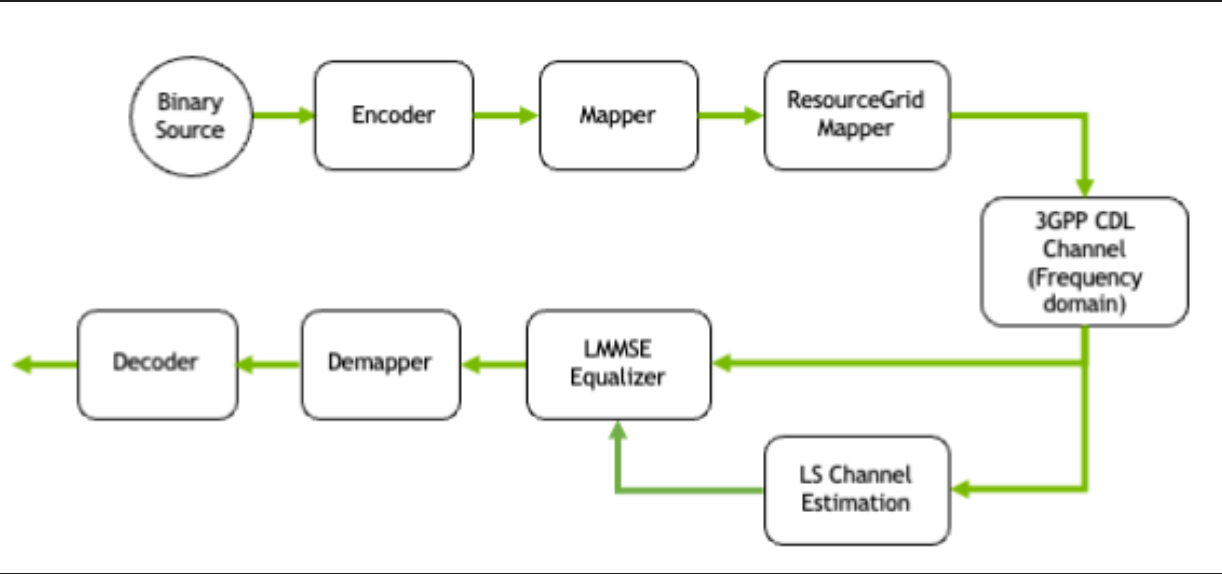

This part is using MATLAB's 5G toolbox.

5G Toolbox™ provides standard-compliant functions and reference examples for the modeling, simulation, and verification of 5G and 5G-Advanced communications systems. The toolbox supports waveform generation, link-level and system-level simulations, golden reference verification, and conformance testing.

## 1) Configuration Overview 

In this experiment, we will configure a **single UT** (equipped with a **single antenna**) and a **single BS** (equipped with **multiple antennas**).

We configure the system such that the number of streams per transmitter (in both uplink and downwlink) is equal to the number of UT antennas.

clear
close all

Define the number of UT and BS antennas

NUM_UT = 1;
NUM_BS = 1;
NUM_UT_ANT = 1;

**You have a choice between 2 Receive Antennas or 4 Receive Antennas. Pick the value below: **

NUM_BS_ANT = 2; 

 The number of transmitted streams is equal to the number of UT antennas

NUM_STREAMS_PER_TX = NUM_UT_ANT;

Create an RX-TX association matrix.

% RX_TX_ASSOCIATION(i,j)=1 means that receiver i gets at least one stream
% from transmitter j.
RX_TX_ASSOCIATION = 1;

## **2) Model Configuration and Setup - Uplink**

### **2.1) OFDM Resource Grid**

The frequency and time representation of placing symbols is the key to understand the operation of 4G and 5G. The transmitted symbols are explicitly mapped to different portion of the two-dimension representation, which consists of a subcarrier axis (frequency) and an OFDM symbol axis (time). This coordinate system is called **resource grid**. Each resource grid contains 12 subcarriers. 

The resource grid contains data symbols and pilots. Let's create the resource grid that spans 26*12 = 312 Subcarriers. 

% Parameters
snrdB = -5:2:5; % SNR in dB
numBitToTx = 1e6;   % Ideally, use 1e8, but it takes time, so you might want to use 1e6 for instance            
perfectChannel = true; % whether use channel estimation or perfect channel

% Create UE/carrier configuration
ue = nrCarrierConfig;
ue.NSizeGrid = 26;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
ue.SubcarrierSpacing = 15;  % 15, 30, 60, 120, 240 (kHz)
ue.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'
nTxAnts = NUM_UT_ANT;  % Number of transmit antennas (1,2,4)
nRxAnts = NUM_BS_ANT;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);
ofdmInfo = nrOFDMInfo(ue);

Based on the 5G standard, set up DMRS for channel estimation.

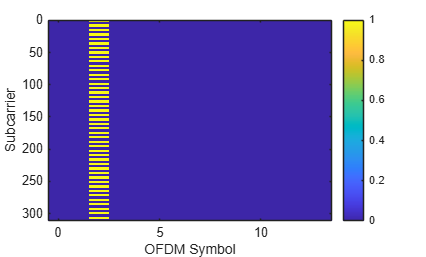

txGrid = nrResourceGrid(ue,nTxAnts);
txGrid = ones(size(txGrid))*0;

% Setup DMRS
pusch = nrPUSCHConfig;
pusch.PRBSet = 0:ue.NSizeGrid-1;
pusch.NID = 0;
dmrsConfig = nrPUSCHDMRSConfig("DMRSTypeAPosition",2,...
    "DMRSConfigurationType",1,...
    "DMRSLength",1,...
    "NumCDMGroupsWithoutData",2,...
    "NIDNSCID",0,...
    "NSCID",0,...
    "NRSID",0,...
    "GroupHopping",0,...
    "SequenceHopping",0);

pusch.DMRS = dmrsConfig;
dmrsSymbols = nrPUSCHDMRS(ue, pusch);
dmrsIndices = nrPUSCHDMRSIndices(ue, pusch);
dmrsGrid = txGrid;
dmrsGrid(dmrsIndices) = dmrsSymbols;
txGrid = dmrsGrid;

figure;imagesc([0 ue.SymbolsPerSlot-1],[0 ue.NSizeGrid*12-1],abs(txGrid));xlabel('OFDM Symbol');ylabel('Subcarrier')
colorbar

fftsize = ofdmInfo.Nfft;

**6. Questions: Comment on the Resource Grid according to the parameter set in the codes**

Try to alter **some parameters** and observe the OFDM resource grid accordingly.

After some trials, restore the default parameters: 

```

`   num_ofdm_symbols=14,`

`   fft_size=512,`

`   num_tx=NUM_UT,`

`   num_streams_per_tx=NUM_STREAMS_PER_TX,`

`   cyclic_prefix_length=6,`

`   dc_null=True,`

`   pilot_ofdm_symbol_indices=[2,3])`

```

In the default example, it is observed that the resource grid spans 512 subcarriers over 14 OFDM symbols. A DC guard carrier as well as some guard carriers to the left and right of the spectrum are nulled. The third and twelfth OFDM symbol are dedicated to pilot transmissions.

**7. Questions: Do you know why the fft_size is 512?**

In the next session, we generate random pilot signals and random data.

### **2.2) Conventional TX System**

#### **2.2.1) Binary Source**

Binary Source object can be created by the following code. 

% Generate pilot sequence data sequence
modulationType = {'QPSK','16QAM','64QAM','256QAM'};
s = RandStream("mt19937ar",Seed=128);
pilots = 2 * randi(s,[0,1],1,ofdmInfo.Nfft) - 1;

Calculating the total number of data symbols in frequency domain per slot

num_data_symbols_per_slot = ue.NSizeGrid*12*(ue.SymbolsPerSlot-dmrsConfig.DMRSLength);

Calculating the number of information bits in each slot and the corresponding number of slots to transmit the numBitToTx

num_bits_per_symbol = 2; % QPSK modulation
modulation = modulationType{round(num_bits_per_symbol/2)};
codeRate = 0.5; % Target code rate, a real number between 0 and 1
n = round(num_data_symbols_per_slot*num_bits_per_symbol); % Number of coded bits
k = round(n*codeRate); % Number of information bits
numSlots = ceil(numBitToTx/k); % number of slots
dataSeq = randi(s,[0,1],k,1,'int8');

#### **2.2.2) LDPC Forward Error Correction Encoder**

5G LDPC FEC object can be created by the following code.

TBS = k;            % Transport block size, a positive integer
rv = 0;                % Redundancy version, 0-3
nlayers = 1;           % Number of layers, 1-4 for a transport block
cbsInfo = nrDLSCHInfo(TBS,codeRate);

% Transport block CRC attachment
tbIn = nrCRCEncode(dataSeq,cbsInfo.CRC);

% Code block segmentation and CRC attachment
cbsIn = nrCodeBlockSegmentLDPC(tbIn,cbsInfo.BGN);

% LDPC encoding
codeWord = nrLDPCEncode(cbsIn,cbsInfo.BGN);
modIn = nrRateMatchLDPC(codeWord,n,0,modulation,1);

#### **2.2.3) QAM Modulation**

QAM Modulation can be performed as follow. 

**Task 1. Replace this line below with appropriate function so it accepting QPSK Modulation**

Current modIn dimension is 4056x1 and modSignal is 8112x1

You can use manual function or 5G Toolbox modulation

modSignal = nrSymbolModulate(modIn, modulation);

Validate your answer

ref = load('Reference.mat');
if isequal(size(modSignal), size(ref.modSignal)) && ...
        all(abs(modSignal - ref.modSignal) < 1e-10, 'all')
    Task1_obj=true;
    disp('Correct Answer!');
else
    Task1_obj=false
    disp('Incorrect Answer!');
end

Correct Answer!


#### **2.2.4) OFDM Resource Grid Mapper**

The resource grid mapper maps symbols onto an OFDM resource grid.

dataIdx = setdiff([1:prod(size(txGrid))]',floor(dmrsIndices(1)/size(txGrid,1))*size(txGrid,1)+1: size(txGrid,1)*ceil(dmrsIndices(end)/size(txGrid,1))); 
txGrid(dataIdx) = modSignal;


#### **2.2.5) Antennas**

In this part, we configure the antenna arrays used by the UT and BS, as required in the Channel models, such as CDL from the 3GPP 38.901 specification. The following codes configure a typical antenna array. 

carrier_frequency = 2.6e9; % Carrier frequency in Hz.
lambda = physconst('LightSpeed')/carrier_frequency; % wavelength of carrier frequency
bsAntenna = phased.NRAntennaElement(PolarizationModel = 2);
utAtenna = phased.IsotropicAntennaElement;
ut_array = phased.NRRectangularPanelArray(ElementSet={utAtenna},Size = [1 NUM_UT_ANT 1 1],Spacing = [0.5*lambda, 0.5*lambda,0.5*lambda, 0.5*lambda]); % Single Antenna, can be changed to phased.IsotropicAntennaElement for omni
bs_array = phased.NRRectangularPanelArray(ElementSet={bsAntenna},Size = [1 NUM_BS_ANT 1 1],Spacing = [0.5*lambda, 0.5*lambda,0.5*lambda, 0.5*lambda]);

Array geometry

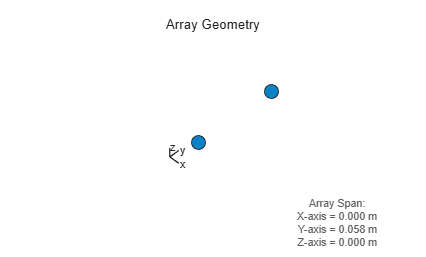

figure
viewArray(bs_array)

The base station array 3-D radiation pattern. 

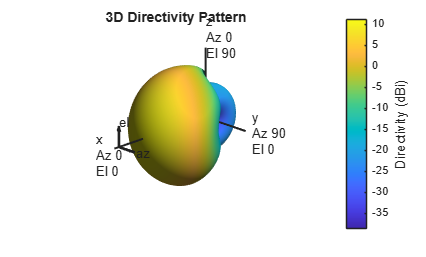

figure
pattern(bs_array,carrier_frequency) 

### 2.3) Channel Model and Conventional RX system

#### **2.3.1) Channel Model**

3GPP TR 38.901 has several channel models such as Clustered Delay Line (CDL) and tapped delay line (TDL).

Clustered Delay Line (CDL) is a type of channel model when the received signal is composed of a number of separate delayed clusters. Each cluster contains a number of multipath components with the same delay but different Angle of Departure and Angle of Arrival.

A CDL channel is considered in this experiment and its model can be created with the following codes.

**The models “A”, “B”, and “C” are non-line-of-sight (NLOS) models, while “D” and “E” are LOS.**

delay_spead = 100e-9;
speed = 10;                % UT radial speed m/s
MaximumDopplerShift = carrier_frequency*speed/physconst('LightSpeed');
channelType = "CDL-A"; % TDL-A, TDL-B, ..., TDL-D, CDL-A...CDL-E

if strfind(channelType,"TDL") 
    channel = nrTDLChannel(DelayProfile=channelType,...
        NumTransmitAntennas=NUM_UT_ANT,...
        NumReceiveAntennas= NUM_BS_ANT,...
        MaximumDopplerShift=MaximumDopplerShift,...
        DelaySpread=delay_spead,...
        ChannelResponseOutput = "ofdm-response",...
        SampleRate = ofdmInfo.SampleRate,...
        Seed = 5);
else
    channel = nrCDLChannel(DelayProfile=channelType,...
        CarrierFrequency=carrier_frequency,...
        TransmitAntennaArray=ut_array,...
        ReceiveAntennaArray= bs_array,...
        MaximumDopplerShift=MaximumDopplerShift,...
        DelaySpread=delay_spead,...
        SampleDensity= 64,...
        SampleRate = ofdmInfo.SampleRate,...
        RandomStream="mt19937ar with seed",...
        Seed=5,...
        ChannelResponseOutput = "path-gains" );

end 

chInfo = info(channel);
maxChDelay = chInfo.MaximumChannelDelay;
txWaveform = nrOFDMModulate(ue,txGrid);
txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];

Based on the setting of the channel object, applying channel response to the transmitter signal and obtain the perfect channel response.

Add noise to the received signal according to the SNR setting.

To solve the inter-symbol-interference, the sync is acquired and the time offset if removed. 

reset(channel);
if channel.ChannelResponseOutput == "ofdm-response"
    [rxWaveform, hest_F_perfect,timeOffset] = channel(txWaveform,ue);
    pathFilters = getPathFilters(channel);
       
else
    [rxWaveform, channelGain,SampleTime] = channel(txWaveform);
    pathFilters = getPathFilters(channel);
    [timeOffset,mag] = nrPerfectTimingEstimate(channelGain,pathFilters);
    hest_F_perfect = nrPerfectChannelEstimate(ue,channelGain,pathFilters,timeOffset,SampleTime);
end

Plotting Channel

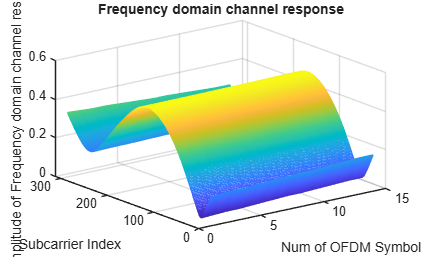

figure
mesh(abs(hest_F_perfect(:,:,1)))
title ("Frequency domain channel response")
xlabel("Num of OFDM Symbol")
ylabel("Subcarrier Index")
zlabel("Amplitude of Frequency domain channel response")

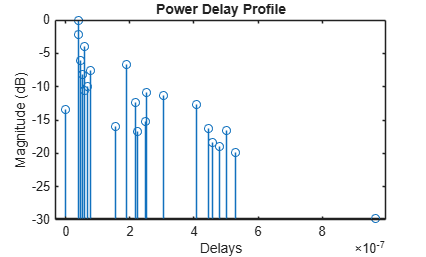

figure
stem(chInfo.PathDelays,chInfo.AveragePathGains,'BaseValue',min(chInfo.AveragePathGains));
title("Power Delay Profile");
xlabel("Delays")
ylabel("Magnitude (dB)")

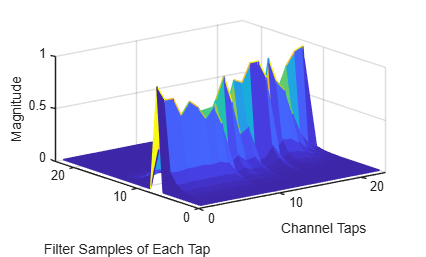

figure
mesh(abs(pathFilters),"FaceColor","flat")
xlabel("Channel Taps")
ylabel("Filter Samples of Each Tap")
zlabel("Magnitude")

Received signal

% adding noise to received signal
[rxWaveform_awgn,nVar] = awgn(rxWaveform,snrdB(end),'measured',25);

% remove the time offset - assumed perfect sync
rxWaveform_synced = rxWaveform_awgn(1+timeOffset:end,:);

#### **2.3.1) Least Square Channel (LS) Estimation**

Demodulate the received OFDM waveform

rx_sym_F = nrOFDMDemodulate(ue,rxWaveform_synced);

Reshape the demodulated symbols for equalization

rx_sym_F_ant = reshape(rx_sym_F,size(rx_sym_F,1)*size(rx_sym_F,2),size(rx_sym_F,3));


The receiver does not know the wireless channel and therefore needs to estimate it before equalization. In 5G NR, known **Demodulation Reference Signals (DM-RS)** are inserted into selected resource elements and can be used as pilots for channel estimation. At DMRS location, a simple Least Squares channel estimation can be implemented through a function called `nrChannelEstimate. nrChannelEstimate` function uses the received resource grid together with the known DM-RS locations and symbols to estimate the channel. The estimates obtained at the reference-signal locations are averaged and interpolated to provide channel estimates for the resource grid. The function also returns an estimate of the noise variance.

From this simulation, `nrChannelEstimate has input and output as below:`

**Input:**

ue : 5G NR carrier configuration. 

rx_sym_F:  Received OFDM resource grid. 

dmrsIndices: Locations of the known DM-RS pilot symbols in the resource grid. 

dmrsSymbols: Known transmitted DM-RS symbols. 

AveragingWindow: Controls the averaging of channel estimates before interpolation. In this simulation you can use 'AveragingWindow',[0 13]

**Output:**

hEst Estimated channel response over the resource grid. 

nvar Estimated noise variance.

**Task 2: Replace this line below with appropriate function so it is doing channel estimation using appropriate input and output above**

[hEst,nvar] = nrChannelEstimate(ue,rx_sym_F, ...
    dmrsIndices,dmrsSymbols,'AveragingWindow',[0 13]);


Validate your answer

if isequal(size(hEst),size(ref.hEst)) && ...
        all(abs(hEst-ref.hEst)<1e-1,'all') && ...
        abs(nvar-ref.nvar)<1e-1

    Task2_obj = true;
    disp('Correct Answer!');

else

    Task2_obj = false;
    disp('Incorrect Answer!');

end

Correct Answer!


Reshape the channel estimates for further processing

hEst_ant =  reshape(hEst,size(hEst,1)*size(hEst,2),size(hEst,3));

Perfect channel response

% Reshape the perfect channel estimates for equalization
hest_F_perfect_ant =  reshape(hest_F_perfect,size(hest_F_perfect,1)*size(hest_F_perfect,2),size(hest_F_perfect,3));

#### **2.3.2) Linear Minimum Mean Square Error (LMMSE) Equalizer**

Perform MMSE equalization on the received symbols

The received symbols are distorted by the wireless channel and noise. An equalizer is therefore required to compensate for the channel effect before symbol demodulation.

In this experiment, We will demonstrate the built-in `nrEqualizeMMSE` function is actually performing the standard LMMSE equation.


$${\mathrm{eqsym}}_{\mathrm{LMMSE}} =\frac{\sum_{r=1}^{N_r } {h_r }^H Y}{\sum_{r=1}^{N_r } {\left|h_r \right|}^2 +\mathrm{nVar}}$$


**Task 3: Your task will be implementing the equation of eqsym_LMMSE and compare it with built in nrEqualizeMMSE make sure that error return close to zero value (e-15)**

if perfectChannel
    %Using Perfect channel response
    [eqsym,csi]= nrEqualizeMMSE(rx_sym_F_ant,hest_F_perfect_ant,nVar);
    H = hest_F_perfect_ant;
    Y = rx_sym_F_ant;
    eqsym_LMMSE = sum(conj(H).*Y,2) ./ ...
    (sum(abs(H).^2,2) + nVar);
    %put the answer here
    error = max(abs(eqsym - eqsym_LMMSE))
else
    % Using Estimated channel
    [eqsym,csi]= nrEqualizeMMSE(rx_sym_F_ant,hEst_ant,nVar);

end

error = 8.6711e-16

#### **2.3.3) QAM Demodulation**

`The demapper produces LLR for all coded bits`

**Task 4. Replace this line below with appropriate function so it is doing QPSK Demodulation**

Current modIn dimension is 4056x1 and modSignal is 8112x1

You can use manual function or 5G Toolbox modulation

% softLLRs = nrSymbolDemodulate(eqsym(dataIdx),modulation,nVar);
softLLRs = nrSymbolDemodulate (eqsym (dataIdx),'QPSK');

Validate your answer

if isequal(size(softLLRs),size(ref.softLLRs)) && ...
        all(abs(softLLRs-ref.softLLRs)<1e-8,'all')

    Task4_obj = true;
    disp('Correct Answer!');

else

    Task4_obj = false;
    disp('Incorrect Answer!');

end

Correct Answer!


#### **2.3.4) LDPC Decoder**

Recover the transmitted rate using LDPC decoding

raterec = nrRateRecoverLDPC(softLLRs,TBS,codeRate,0,modulation,1);

Decode the received information using LDPC with a maximum of 10 iterations

rxInfo = nrLDPCDecode(raterec,cbsInfo.BGN,10);


#### **2.3.5) Perform Error Checking and Plot The Results**

numErrors = sum(rxInfo(1:numel(dataSeq)) ~= dataSeq);
disp(['Number of errors: ', num2str(numErrors)]);

Number of errors: 14


BER=numErrors/numel(dataSeq);
fprintf('BER: %.6g\n', BER);

BER: 0.00345168


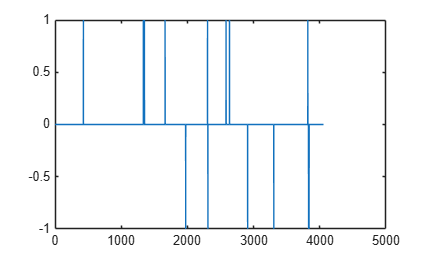

plot(rxInfo(1:numel(dataSeq)) - dataSeq)

## 3) Exercise

**8. Explain the Workflow of the OFDM simulation. **(refer to the figure at the beginning of Exp2)

**9. Explain what channel impulse response and path gain are.  **

**10. Explain how channel estimation works.**

**11. Observe and comment Uplink performance over different CDL channel models.**

**12. What is the impact of increasing the number of receive antennas? **(Plot the BER curve for both 2 and 4 receive antennas)

# Experiment 3: AI-Native Fully Convolutional Receiver

This example shows how to train and use an AI-native, fully convolutional receiver known as DeepRx [1]. Using DeepRx, you replace channel estimation, equalization, and symbol demodulation operations with a deep convolutional neural network (DCNN) at the receiver end of a 5G New Radio (NR) link. DeepRx is particularly beneficial in high Doppler shift scenarios and sparse pilot configurations. In this example, you create a physical uplink shared channel (PUSCH) end-to-end link that consists of a transmitter, a channel, a receiver to generate training, validation and test data. You then assess the performance of DeepRx and compare it with a conventional receiver.

## 1) Introduction

AI-native air interface (AI-AI) is a promising technique for improving system performance and reducing energy consumption, essential steps in developing networks beyond 5G. AI-AI is a departure from the traditional approach of designing and productizing communications systems, as it involves the integration of AI and machine learning (AI/ML) as a core component of the physical layer (PHY) processing.

The 3rd Generation Partnership Project (3GPP) has initiated comprehensive study and work items focused on exploring the applications of AI/ML, with the goal of covering long-term projects such as technologies beyond 5G [2, 3, 4]. In Release 18, researchers, engineers, and companies explored three promising pilot areas – AI/ML-based channel state information (CSI) compression, beam management, and positioning. For more information, see the [CSI Feedback with Autoencoders](docid:comm_ug#example-CSICompressionAutoencoder), [Neural Network for Beam Selection](docid:5g_ug#mw_f8a84489-c1a4-4672-a252-04c6126f855d), and [AI for Positioning Accuracy Enhancement](docid:5g_ug#mw_fa419ac7-9c97-452c-8e57-7e26b70e565d) examples. In Release 19, the team continues to study AI/ML applications for beam management and positioning as work items (WI) and provides specification support [5].

This example demonstrates an AI-AI implementation that replaces multiple 5G receiver processing blocks with AI/ML counterparts to enhance coded bit error ratio (BER) and throughput performance. For a testbench that replaces a 5G receiver with an AI-native receiver using PyTorch™, see the [Verify Performance of 6G AI-Native Receiver Using MATLAB and PyTorch Coexecution](docid:5g_ug#mw_f9282dea-57d3-4773-8a14-f6d4b6ec8eb8) example.

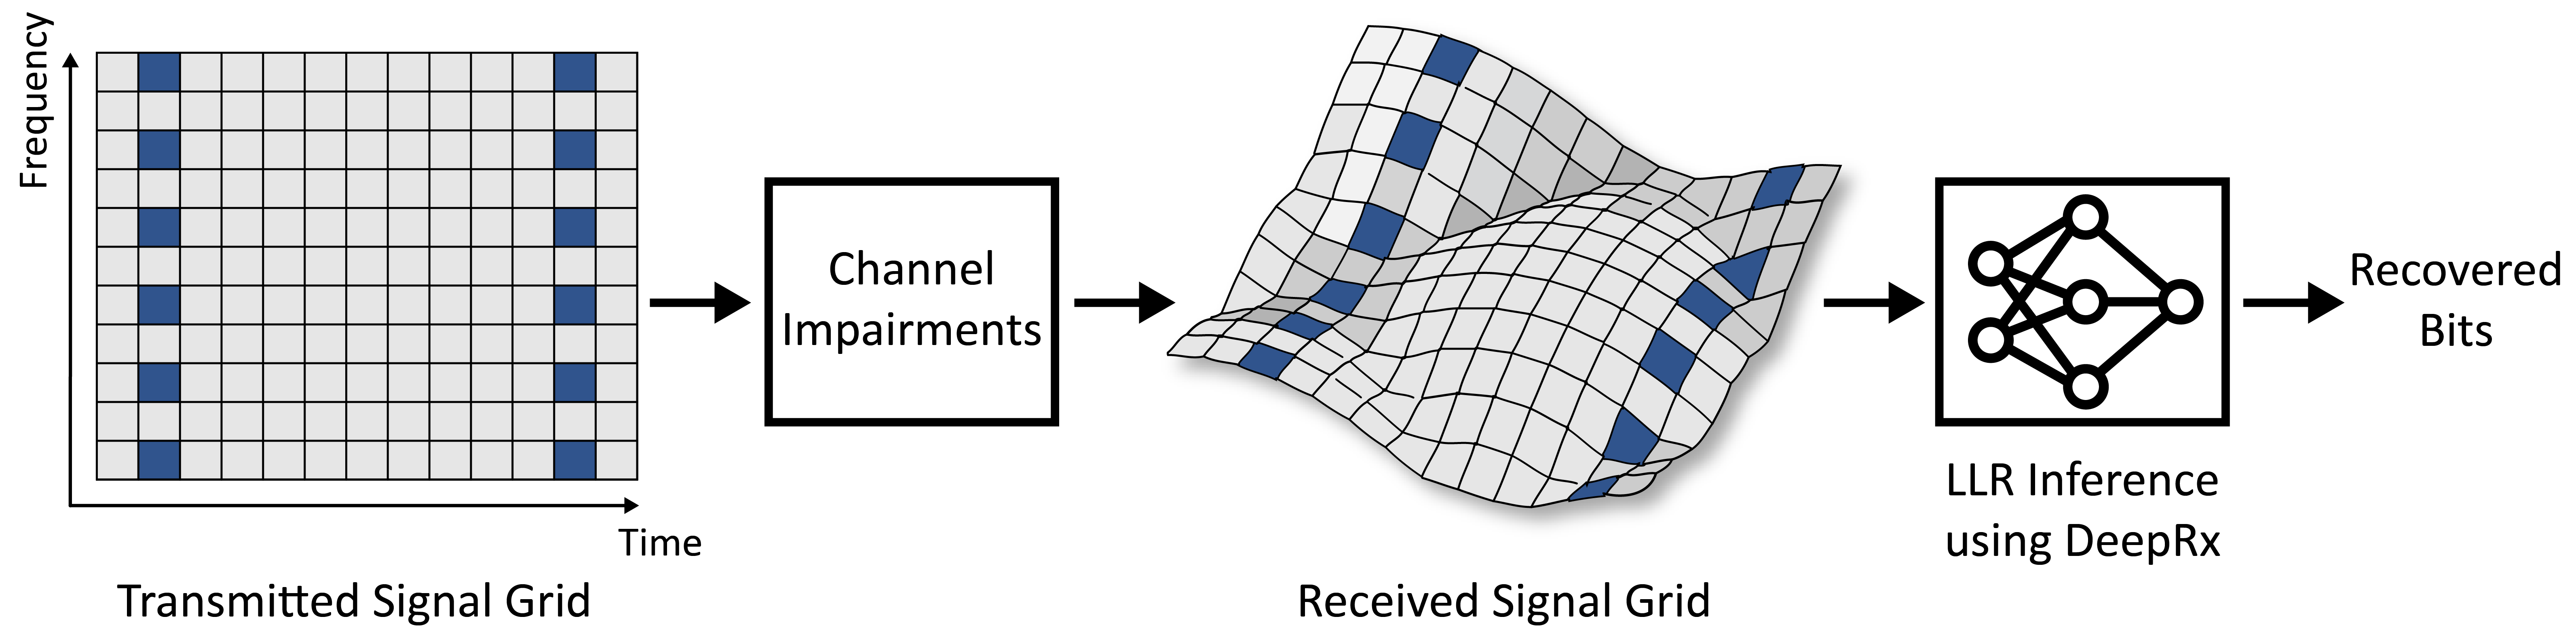

TrainNow      = false; % If true, train the network; otherwise, use a pretrained network 

Model_DeepRx_2ants_1M.mat contains a deep learning network that was trained with 2 million iterations for 2 receive antenna. - you do not want to retrain it yourself! 

Model_DeepRx_4ants_100K.mat contains a deep learning network that was trained with 100,000 iterations for 4 receive antenna - even that takes a very long time (see training below - almost 23 hours with a GPU)  

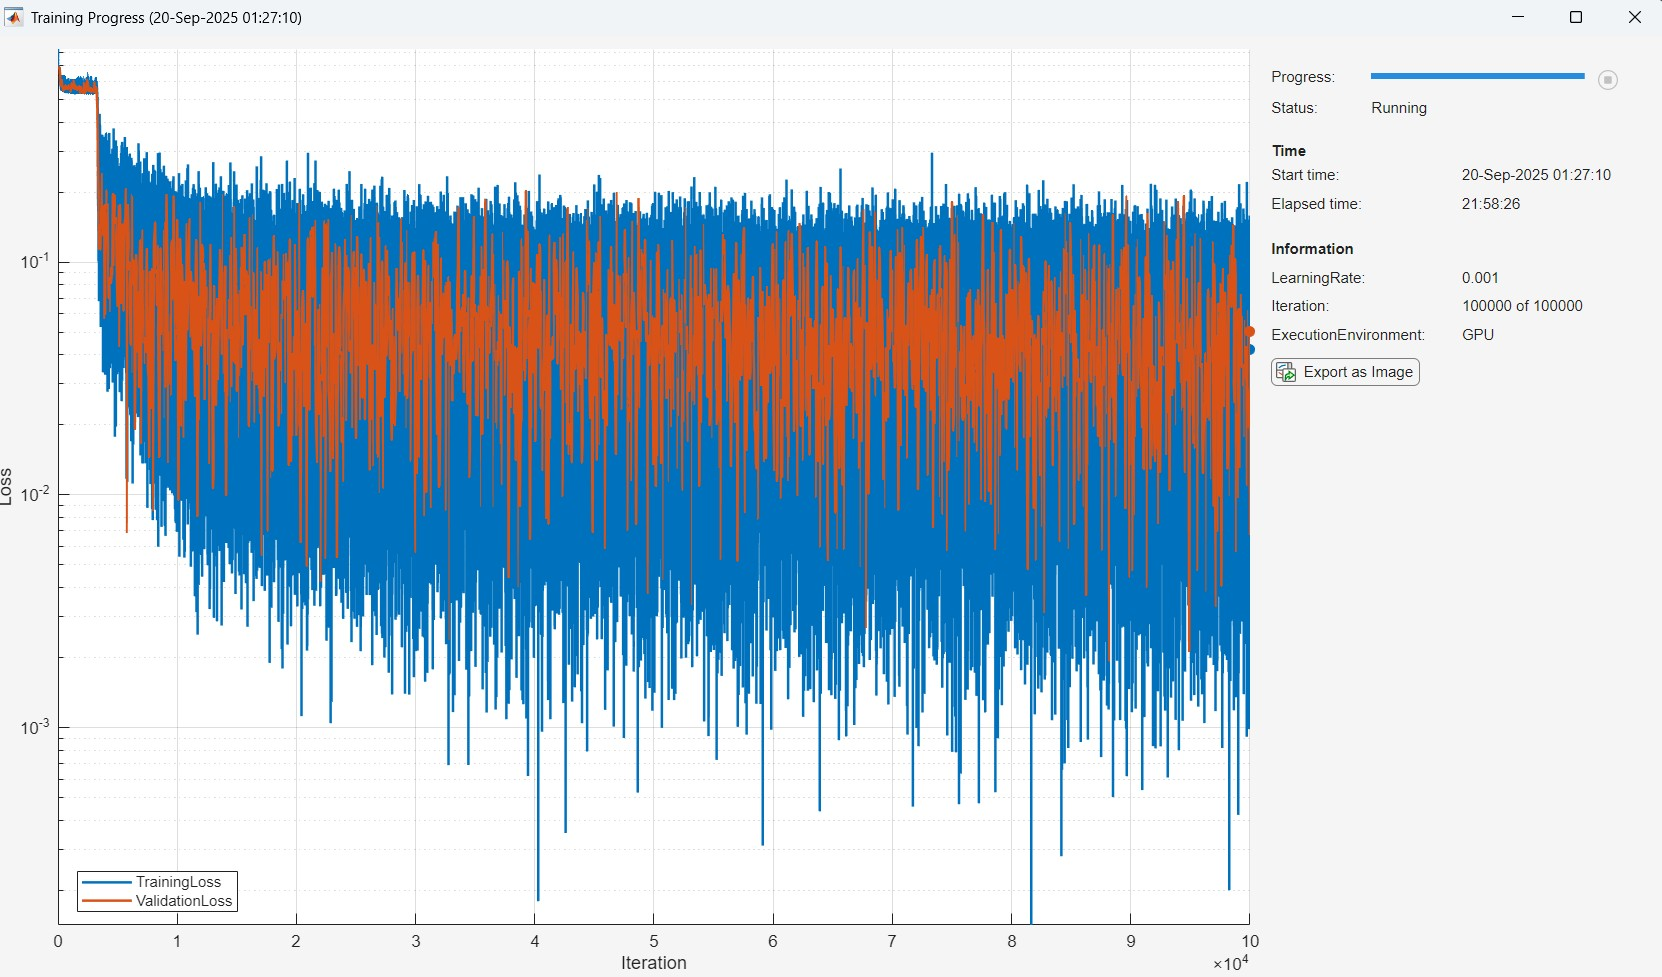

**If you retrain the network (TrainNow = True), you can change the number of iteration for training if needed. **

        The default value is 1000 iterations for training, which takes 13 minutes using my GPU.   

        Without a good GPU, reduce the number of iterations, maybe to 100 (to see at least 2 validation values) or 200. 

NTrainSamples = 1000 ; % If true, train the network; otherwise, use a pretrained network   

if TrainNow == false  
    if NUM_BS_ANT == 2
        data = load("Model_DeepRx_2ants_1M.mat");       % Loading pretrained network 
    elseif NUM_BS_ANT == 4
        data = load("Model_DeepRx_4ants_100K.mat");       % Loading pretrained network 
    end 
    net = data.net;
    netParam = data.netParam; 
elseif TrainNow == true  
    open('AIreceiver.mlx') % Open the function doing the training of the network (for you to have a read if interested in AI) 
    net = AIreceiver(NTrainSamples, NUM_BS_ANT);     % Retraining the network  
    open('ELEC_5508_Lab7_main.mlx') % Back to main script once you see the training is finished 
end 

**Open Deep Network Designer App to visualise the trained Neural Network **

[Deep Network Designer App - Interactively create and edit deep learning networks](https://au.mathworks.com/help/deeplearning/deep-network-designer-app.html) 

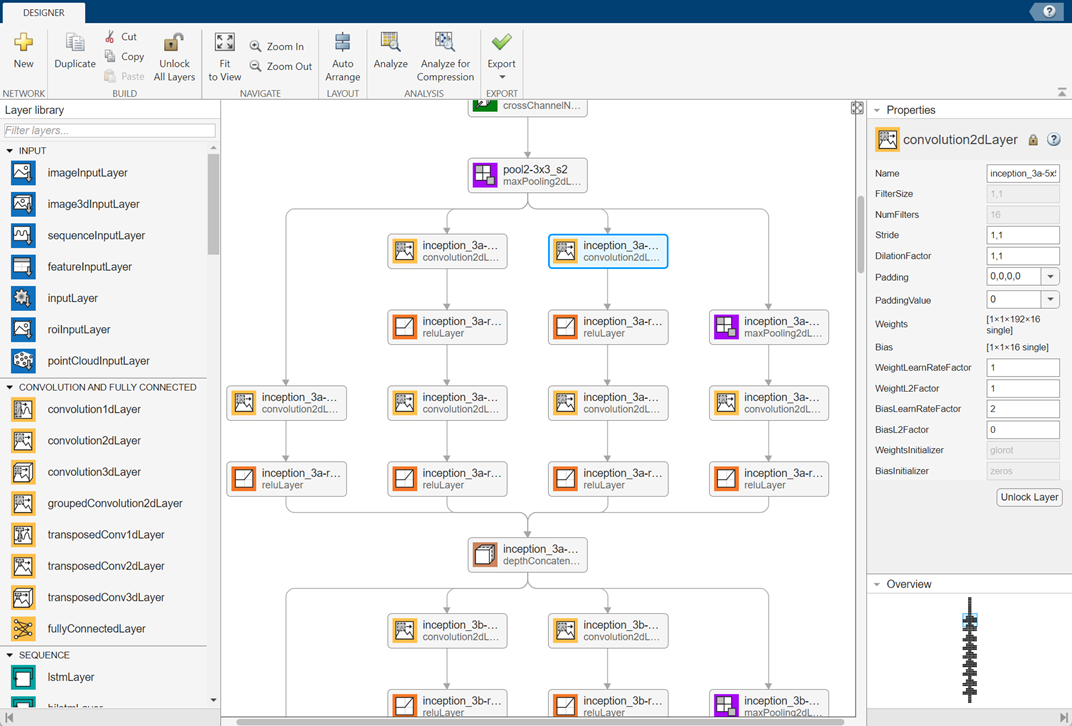

deepNetworkDesigner(net)

**If it was already open before and you get the message below, **

**click on "Replace" to visualise the new network **

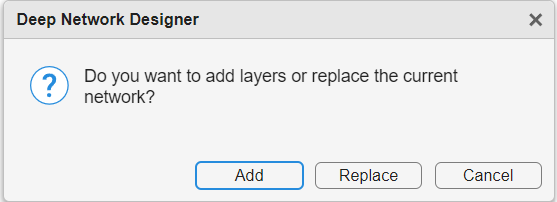

## 2) Running the transceiver

The transceiver is following the below workflow:

**Task 5: The section over here is incomplete, you need to troubleshoot to get the correct result using setup below**

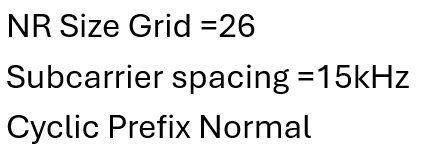

ue = nrCarrierConfig;
ue.NSizeGrid         = 26;
ue.SubcarrierSpacing = 15;
ue.CyclicPrefix      = 'Normal';
ofdmInfo_transceiver = nrOFDMInfo(ue);   % was undefined, used for nVar in the Rx loop
ofdmInfo             = ofdmInfo_transceiver;

perfectChannel = false;

Transmitter Block

numBitTxed = zeros(1,numel(snrdB));
numBitError = zeros(1,numel(snrdB));
numBitErrorAI = zeros(1,numel(snrdB));
numUncodedBitTxed = zeros(1,numel(snrdB));
numUncodedBitError = zeros(1,numel(snrdB));
numUncodedBitErrorAI = zeros(1,numel(snrdB));
                   
%% Tx side
% Generate transport block
dataSeq = dataSeq;
% LDPC coding
tbIn = nrCRCEncode(dataSeq,cbsInfo.CRC);
cbsIn = nrCodeBlockSegmentLDPC(tbIn,cbsInfo.BGN);
codeWord = nrLDPCEncode(cbsIn,cbsInfo.BGN);
modIn = nrRateMatchLDPC(codeWord,n,0,modulation,1); % code rate match
% QAM Modulation
modSignal = nrSymbolModulate(modIn, modulation);

% OFDM modulation
txGrid(dataIdx) = modSignal;
txWaveform = nrOFDMModulate(ue,txGrid);
% Patching txsignal for multipath delay
txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];

Channel Block                  

%% Passing through 5G channel
% channel is set to use global random stream - the reset method
% will only reset channel filters, aka to makesure there is no
% residual signals in the filter when next Slot came. 
reset(channel);
if channel.ChannelResponseOutput == "ofdm-response"
    [rxWaveform, hest_F_perfect,timeOffset] = channel(txWaveform,ue);
    pathFilters = getPathFilters(channel);
else
    [rxWaveform, channelGain,SampleTime] = channel(txWaveform);
    pathFilters = getPathFilters(channel);
    timeOffset = nrPerfectTimingEstimate(channelGain,pathFilters);
    hest_F_perfect = nrPerfectChannelEstimate(ue,channelGain,pathFilters,timeOffset,SampleTime);
end

Receiver Block

rng(25);
for snrIdx = 1:numel(snrdB)
    
    % Displaying progress 
    disp(['SNR points ',num2str(snrIdx),' out of ', num2str(numel(snrdB))]) 
    
    snrCurrent = snrdB(snrIdx);
    snrL = 10^(snrCurrent/10);
    N0 = 1/sqrt(NUM_BS_ANT*double(ofdmInfo.Nfft)*snrL);
    nVar = N0^2*double(ofdmInfo_transceiver.Nfft);
    
    for slotIdx = 1:numSlots                    
        % adding noise to received signal
        rxWaveform_awgn = awgn(rxWaveform,snrCurrent,'measured');

        %% Receiver side
        % remove the time offset - assumed perfect sync
        rxWaveform_synced = rxWaveform_awgn(1+timeOffset:end,:);
        % Demodulate the received OFDM waveform
        rx_sym_F = nrOFDMDemodulate(ue,rxWaveform_synced);
     
        % Reshape the demodulated symbols for equalization

        %% Conventional receiver
        rx_sym_F_ant = reshape(rx_sym_F,size(rx_sym_F,1)*size(rx_sym_F,2),size(rx_sym_F,3));


        if perfectChannel
            % Reshape the perfect channel estimates for equalization
            hest_F_perfect_ant =  reshape(hest_F_perfect,size(hest_F_perfect,1)*size(hest_F_perfect,2),size(hest_F_perfect,3));
            % MMSE equalization
            [eqsym,csi] = nrEqualizeMMSE(rx_sym_F_ant, hest_F_perfect_ant, nVar);

        else
            % FIX: LS channel estimation (same as your Task 2)
            [hEst,nvar] = nrChannelEstimate(ue,rx_sym_F,dmrsIndices,dmrsSymbols, ...
                                            'AveragingWindow',[0 13]);
            hEst_ant = reshape(hEst,size(hEst,1)*size(hEst,2),size(hEst,3));
            % FIX: MMSE equalisation with the ESTIMATED channel
            % (the original code just repeated the hEst = ones(...) placeholder here)
            [eqsym,csi] = nrEqualizeMMSE(rx_sym_F_ant,hEst_ant,nvar);

        end


        % QAM demodulation
        softLLRs = nrSymbolDemodulate(eqsym(dataIdx), modulation, nVar);
        softLLRs = softLLRs .* repelem(csi(dataIdx), 2);   % weight each bit by its RE's channel quality

        % LDPC decoding
        % Recover the transmitted rate using LDPC decoding
        raterec = nrRateRecoverLDPC(softLLRs,TBS,codeRate,0,modulation,1);
        
        % Decode the received information using LDPC with a maximum of 10 iterations
        rxInfo = nrLDPCDecode(raterec,cbsInfo.BGN,10);

        %% AI receiver 
        rawChanEstGrid = rx_sym_F.*conj(dmrsGrid);
        X = cat(3, real(rx_sym_F), imag(rx_sym_F), ...
            real(dmrsGrid), imag(dmrsGrid), ...
            real(rawChanEstGrid), imag(rawChanEstGrid));
        L = predict(net, dlarray(X, 'SSCB'));
        extractedLLRs = nrExtractResources(dataIdx,-L(:,:,1:2));
        ulschLLRs = reshape(gather(extractdata(extractedLLRs.')), [], 1);

        raterecAI =nrRateRecoverLDPC(ulschLLRs,TBS,codeRate,0,modulation,1);
        rxInfoAI = nrLDPCDecode(raterecAI,cbsInfo.BGN,10);
        
        % Conventional receiver
        numUncodedErrors = sum(xor(softLLRs <= 0, modIn));
        numErrors = sum(rxInfo(1:numel(dataSeq)) ~= dataSeq);
        % AI receiver
        numUncodedErrorsAI = sum(xor(ulschLLRs <= 0, modIn));
        numErrorsAI = sum(rxInfoAI(1:numel(dataSeq)) ~= dataSeq);
        % Accumulate total transmitted bits
        numBitTxed(snrIdx) = numBitTxed(snrIdx) + k;
        numUncodedBitTxed(snrIdx) = numUncodedBitTxed(snrIdx) + n;
        % Accumulate conventional errors
        numBitError(snrIdx) = numBitError(snrIdx) + numErrors;
        numUncodedBitError(snrIdx) = numUncodedBitError(snrIdx) + numUncodedErrors;

        % Accumulate AI errors
        numBitErrorAI(snrIdx) = numBitErrorAI(snrIdx) + numErrorsAI;
        numUncodedBitErrorAI(snrIdx) = numUncodedBitErrorAI(snrIdx) + numUncodedErrorsAI;

    end
    
end

SNR points 1 out of 6
SNR points 2 out of 6
SNR points 3 out of 6
SNR points 4 out of 6
SNR points 5 out of 6
SNR points 6 out of 6


## 3) Plotting Bit Error rate for Pre-Trained AI Receiver vs Conventional Receiver

Answer

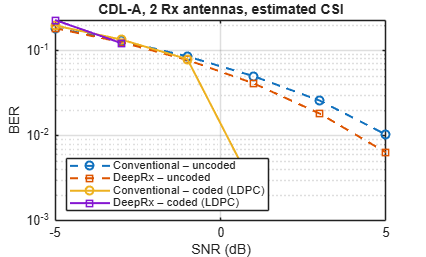

BER        = numBitError          ./ numBitTxed;
BER_AI     = numBitErrorAI        ./ numBitTxed;
uncBER     = numUncodedBitError   ./ numUncodedBitTxed;
uncBER_AI  = numUncodedBitErrorAI ./ numUncodedBitTxed;

figure
semilogy(snrdB,uncBER,'--o', snrdB,uncBER_AI,'--s', ...
    snrdB,BER,'-o',     snrdB,BER_AI,'-s','LineWidth',1.5)
grid on
xlabel('SNR (dB)'); ylabel('BER')
legend('Conventional – uncoded','DeepRx – uncoded', ...
    'Conventional – coded (LDPC)','DeepRx – coded (LDPC)','Location','southwest')
csiLabel = "estimated"; if perfectChannel, csiLabel = "perfect"; end
title(sprintf('%s, %d Rx antennas, %s CSI', channelType, NUM_BS_ANT, csiLabel))

Specific Resource Element Channel Estimation and Symbol Detection

The OFDM resource grid consists of NSizeGrid=26 resource blocks, each containing 12 subcarriers, and ue.SymbolsPerSlot=14 OFDM symbols within one slot.

Therefore, the resource grid has the following dimensions:


$$[
26\times12\times14=312\times14
]$$


Each resource element represents one specific subcarrier and OFDM symbol. The transmitted resource grid contains both data symbols and known Demodulation Reference Signals (DM-RS), which are used for channel estimation. In this exercise, you will investigate channel estimation and symbol detection at specific resource element locations.

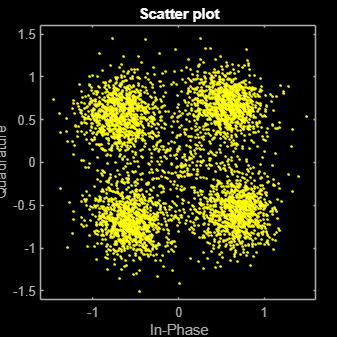

% Selected resource element
rb = 5;
sc = 5;
sym = 5;
% Convert resource block and subcarrier to grid coordinates
k_loc = (rb-1)*12 + sc;
% Convert to linear index
idx = sub2ind([ue.NSizeGrid*12, ue.SymbolsPerSlot],k_loc,sym);
% Extract received signal and estimated channel
Y = rx_sym_F_ant(idx,:);
H = hest_F_perfect_ant(idx,:);
% Equalization at the selected resource element
[xEst,~] = nrEqualizeMMSE(Y,H,nVar);
% Extract result from the existing full-grid equalization
xFull = eqsym(idx);
scatterplot(eqsym,1)

% Extract original transmitted QPSK symbol
xTx = txGrid(idx);
% Compare individual and full-grid equalization
errorEq = abs(xEst-xFull);
% Compare equalized and transmitted symbols
errorTx = abs(xEst-xTx);
fprintf('Correct Detection:  %d\n',errorTx);

Correct Detection:  6.187348e-01


## 4) Exercise

**13. Explain why channel estimation is not needed in neural receiver scheme and what will be its advantages in real world applications.**

**14. Explain how the NN receiver works and whether it will still  perform well when the channel model is changed during the testing phase (**The channel model used in training is different from the one in testing**).**

**15. Run the simulation with a pre-trained model and plot the BER curve.**

Group A (odd-numbered group) set NUM_BS_ANT=2

Group B (even-numbered group) set NUM_BS_ANT=4

**Bonus questions **(this is **optional**, and can give you a bonus mark to compensate for losses of the mark on other questions. But this will not make your mark exceed 8) 

**16. Train the NN receiver by yourself with 1000 iterations (**change** trainNow=True** at line 230, and then click **Run to End**), **and then compare the trained model with model provided** **(**i.e., Model_DeepRx_2ants_1M or Model_DeepRx_4ants_100K) **to evaluate their BER performance. What do you observe and what is the reason?**

**17: Try to produce a better trained model than the one you get in Q18 **(increase number of iterations, modify the NN receiver architecture, etc)**. Then evaluate your trained model with the model in Q16 and the provided model. **

**Note: You have to clearly state what you have done for Q17 in the report, and attach your trained model and modified structure to the submission**. (We will evaluate your results based on your trained model)

**28: The BER curve might not be stable due to not enough bits in the simulation (default is 10^6). Try increasing this value and observe the results.**

# **References**

[1] M. Honkala, D. Korpi, and J. M. J. Huttunen, "DeepRx: Fully Convolutional Deep Learning Receiver," in *IEEE Transactions on Wireless Communications*, vol. 20, no. 6, pp. 3925—3940, June 2021.

[2] J. Hoydis, F. A. Aoudia, A. Valcarce, and H. Viswanathan, "Toward a 6G AI-Native Air Interface," in *IEEE Communications Magazine*, vol. 59, no. 5, pp. 76—81, May 2021.

[3] T. O’Shea and J. Hoydis, "An Introduction to Deep Learning for the Physical Layer," in *IEEE Transactions on Cognitive Communications and Networking*, vol. 3, no. 4, pp. 563—575, Dec. 2017.

[4] 3GPP TR 38.843. "Study on Artificial Intelligence (AI)/Machine Learning (ML) for NR air interface" 3rd Generation Partnership Project;  Technical Specification Group Radio Access Network.

[5] 3GPP TSG RAN Meeting #103, Qualcomm, "Revised WID on Artificial  Intelligence (AI)/Machine Learning (ML) for NR Air Interface,"  RP-240774, Maastricht, Netherlands, Mar. 18-21, 2024.

[6] F. Ait Aoudia and J. Hoydis, "End-to-End Learning for OFDM: From Neural Receivers to Pilotless Communication," in *IEEE Transactions on Wireless Communications*, vol. 21, no. 2, pp. 1049—1063, Feb. 2022.

[7] K. He, X. Zhang, S. Ren, and J. Sun, "Deep Residual Learning for Image  Recognition," 2016 IEEE Conference on Computer Vision and Pattern  Recognition (CVPR), Las Vegas, NV, USA, 2016, pp. 770—778.

[8] He, K., Zhang, X., Ren, S., and Sun, J., "Identity mappings in deep  residual networks", in European Conference on Computer Vision, pp.  630—645, Springer, 2016.

[9] F. Chollet, "Xception: Deep Learning with Depthwise Separable  Convolutions," in 2017 IEEE Conference on Computer Vision and Pattern  Recognition (CVPR), Honolulu, HI, USA, 2017 pp. 1800—1807.